## **2023AAPS0013P - Kalaman Filter Implementation**

**Pranav Chandra N.V**

-----x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x----

### Generation of Data

Setting Variables

speed = 1

speed = 1

initial = 0

initial = 0

time = 0

time = 0

sim_time = 60

sim_time = 60

timestep = 1

timestep = 1


timesteps = 0:timestep:sim_time;

First generating our data

true_pos = speed*timesteps;
noise = normrnd(0, sqrt(2), size(timesteps));
positions = true_pos+noise

positions =    -0.4736    1.7818    3.4695    1.4194    5.7828    5.9336    5.9040    6.7239    7.6923    8.5713   10.0326   11.0725   13.1682   15.1595   14.6603   14.7034   16.8842   17.2591   16.5437   20.3424   20.4343   21.1912   22.7287   23.3697   22.6685   24.7704   25.7934   26.2476   30.3789   27.7615   29.3158   29.9931   30.3394   32.7281   33.6124   37.1638   35.6478   35.4950   40.2676   40.7461   39.6753   38.8700   41.3712   42.7795   44.3904   44.6307   46.6271   47.5542   46.2313   47.6594


-----x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x------x----

### Implementation of Alpha-Beta Filter

Now setting up our initial predictions and variables, go ahead and tune alpha and beta to get the best results!

%initial guess variables
pos_guess = 50;
speed_guess = 1;

%some required variables
predictions(61) = [0]

predictions =   550.0000   51.9502 -224.5214 -248.9110 -134.7042   -6.0027   63.1798   70.8697   39.8821    9.8976   -5.9579   -7.0547    3.7578   13.8248   18.7938   17.4716   18.6123   18.0745   17.0977   17.8044   18.8688   18.1767   20.5759   22.0138   22.9289   23.4790   25.0777   24.3833   28.6242   30.9862   31.2780   31.2499   30.5067   33.3868   34.2247   34.1150   37.4191   37.5881   37.2045   37.9115   38.3178   38.8776   45.0830   47.6993   46.4221   43.0772   42.5311   44.8548   48.8333   48.4626


estimations(61) = [pos_guess]

estimations =   275.9751   25.7268 -111.5921 -123.1481  -64.5754   -0.6978   35.0859   37.4840   23.6908    8.8665    0.9059    2.3319    8.0783   13.4360   15.4538   17.0331   17.5538   17.3258   17.5651   18.2169   18.1968   19.3864   20.7001   21.8145   22.6468   23.8622   24.1228   26.3735   28.6798   29.9789   30.6144   30.5606   31.9737   33.0992   33.6071   35.5131   36.5506   36.8775   37.3945   37.8562   38.3669   41.7249   44.7121   45.5671   44.3221   43.4266   44.1407   46.4870   47.4748   47.0838



%setting initial alpha and beta values that we can change to improve
%predictions
alpha = 0.5; 
beta = 0.5;

Now implementing the actual filter, by getting the position "z" for every point until the array is completed.

for z=1:1:((sim_time*(1/timestep))+1)
    %state prediction
    pos_guess = pos_guess + speed_guess*timestep; %guessing the position
    speed_guess = speed_guess;
    predictions(z) = pos_guess;

    %state updation and estimation
    delta = positions(z)-pos_guess;

    pos_guess = pos_guess + alpha*(delta); %alpha filter
    speed_guess = speed_guess + beta*(delta/timestep); %beta filter

    estimations(z) = pos_guess;
end

Plotting graphs (optional)

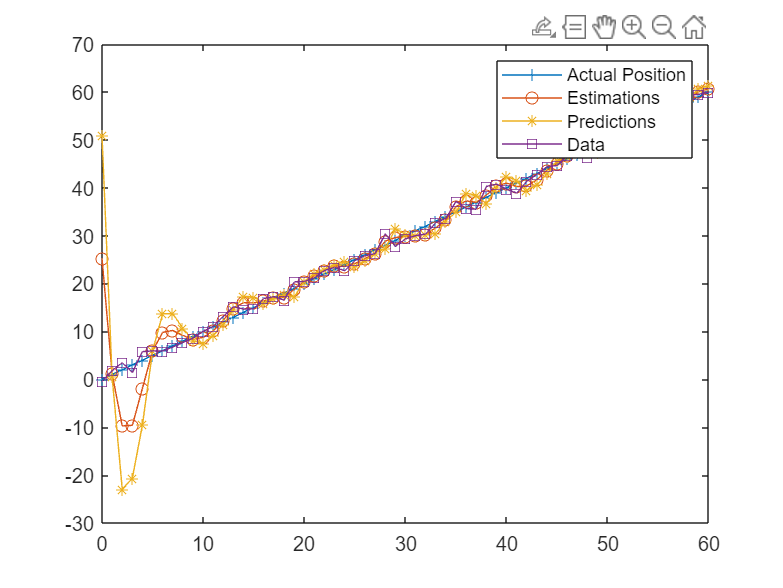

%hold on
plot(timesteps, true_pos, '-+', timesteps, estimations, '-o', timesteps, predictions, '-*', timesteps, positions, '-square')
legend('Actual Position', 'Estimations', 'Predictions', 'Data')

%plot(timesteps, positions, 'square')
%plot(timesteps, estimations, '-o')
%plot(timesteps, predictions, '-*')